## **Retinotopic Mapping: **

`This Live Script runs the retinotopy analysis function with specified parameters.`

**1) Define the input parameters of the imaging session: **

% Define the input parameters
subjectID    = 'Leia17_SpacialMapping'; % Identifier for the subject
sessionDate  = '240909'; % Date of the imgaing session 
nStimLocs    = 4;      % Number of stimulus locations// or size degrees for spatial mapping
nRepsPerLoc  = 25;     % Number of repetitions per location
stimDurS     = 8;      % Duration of stimulus in seconds
baselineDurS = 8;      % Duration of baseline in seconds
respWindowS  = 2;      % Number of seconds of the stimulus to be analyze (at the begining  of stimulus)
blWindowS    = 4;      % Number of seconds of the baseline to be analyze (at the end of baseline)

**2) Call the function: **

% Call the function
[mapData, session] = retinotopy(subjectID, nStimLocs, nRepsPerLoc, stimDurS, baselineDurS, respWindowS, blWindowS);


**3) Visualize the Retinotopic Map: **

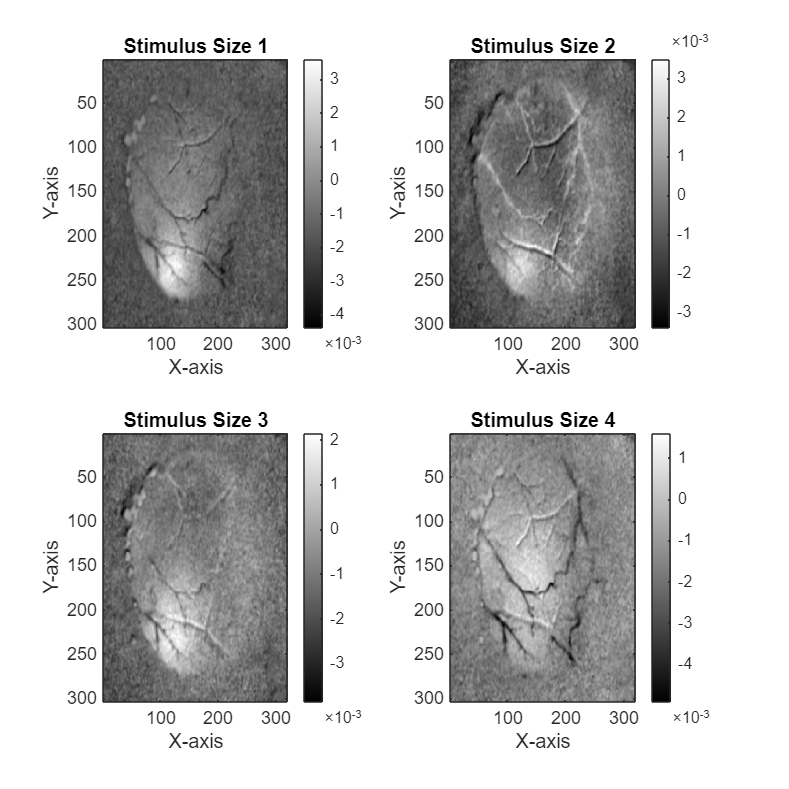

% Average Image Across All Frames
avgImage = mean(mean(session, 3), 4); 
avgImage = imgaussfilt(avgImage);

figure('Position', [10 10 1000 1000]);
hold on;
for locNum = 1:nStimLocs
    subplot(2, 2, locNum);
    imagesc(imgaussfilt(mapData(:, :, locNum), 1.3));
    colormap('gray');
    colorbar;
    title(['Stimulus Size ', num2str(locNum)]);
    xlabel('X-axis'); 
    ylabel('Y-axis');
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**4) Visualize Spacial Mapping: **

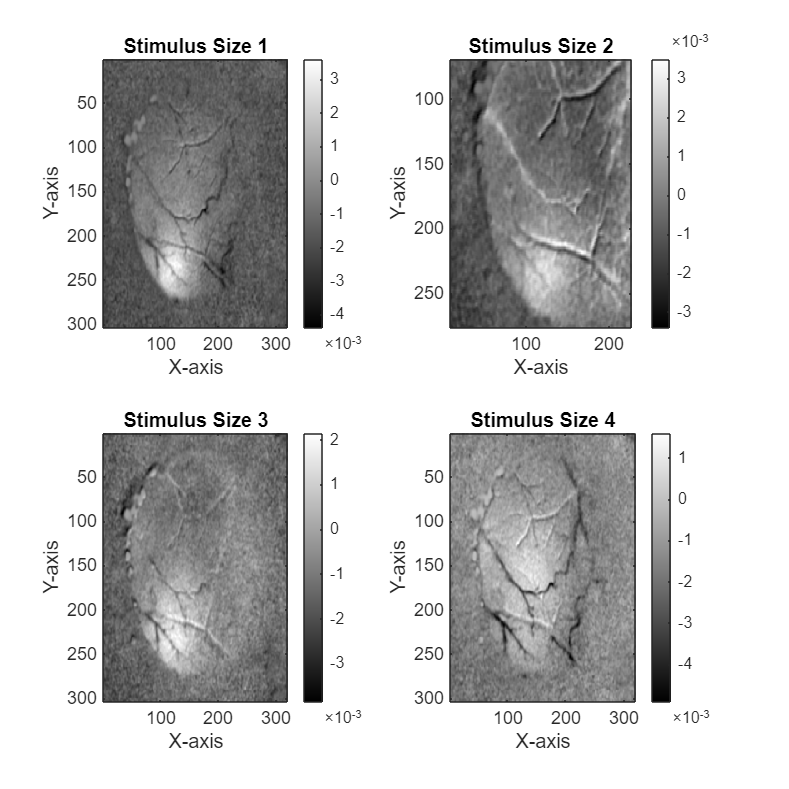

figure('Position', [0 0 1500 300]);

hold on;

sizeIndex = 10;
plotIndex = 1;

% Iterate through stimulus sizes
for locNum = 1:nStimLocs
        subplot(1, nStimLocs, plotIndex);  % Create subplot for each stimSize
        imagesc(imgaussfilt(mapData(:, :, locNum), 1.3));
        colormap('gray');
        colorbar;
        title(['Stimulus Size ', num2str(sizeIndex), ' degrees']);
        xlabel('X-axis'); 
        ylabel('Y-axis');
        plotIndex = plotIndex + 1;  % Increment subplot index for the next plot
        sizeIndex = sizeIndex + 10
end


**5) Save the figure if needed: **

% saveas(gcf, [sessionDate,'_',subjectID,'.png']); % need to adjust the png size 